# INTRODUCTION

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% STUDENT TORNIKE ONOPRISHVILI
% JANUARY OF 2019
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## INITIALIZE MATLAB

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear;
close all;
clc;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## UNITS

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
meters      = 1;
centimeters = 1e-2 * meters;
millimeters = 1e-3 * meters;
micrometers = 1e-6 * meters;
nanometers  = 1e-9 * meters;
inches      = 2.54 * centimeters;
feet        = 12 * inches;

millivolts  = 1e-3;
volts       = 1;
kilovolts   = 1e3;

seconds     = 1;
nanoseconds = 1e-9 * seconds;
picoseconds = 1e-12 * seconds;
femtoseconds= 1e-15 * seconds;

hertz       = 1/seconds;
kilohertz   = 1e3 * hertz;
megahertz   = 1e6 * hertz;
gigahertz   = 1e9 * hertz;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## CONSTANTS

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
eps0 = 8.85418782e-12 * 1/meters;
miu0 = 4*pi*1e-7 * 1/meters;
c0 = 1/sqrt(miu0*eps0) * meters/seconds;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## SIMULATION PARAMETERS

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% SIMULATION MODE
USE_TMZ_MODE = false;
USE_TEZ_MODE = true;

% SOURCE PARAMS
USE_DSRC = false;
USE_ESRC = true;
USE_HSRC = true;

% ADVANCED SIMULATION
USE_ADVANCED_VISUALISATION = true;
DO_DIELECTRIC_SMOOTHING = true;
APPLY_NONLINEARITY = true;
USE_SINGLE_PRECISION = false;

% QUALITY OF LIFE PARAMETERS
DISPLAY_LABELS = true;
AUTO_FPS_ADJUSTMENT = true;
SHUTDOWN_ON_EXIT = false;
PLAY_ON_FINISH = false;
DISPLAY_TRANSFER_WINDOW = true;

% LEARNING OPTIONS
DO_FOURIER_TRANSFORM = false;
DO_TRANSFER_CALCULATION = false;

% ADVANCED TESTING
USE_EMPTY_GRID      = false;
USE_FULL_TFSF_BOX   = false;
USE_TFSF_SOURCE     = true;
USE_HARD_SOURCE     = false;
USE_DIRICHLET_BC    = true;
USE_PERIODIC_BC     = false;

% cases = 1 + logspace(-4,-1,10);
% cases = [cases, 1-logspace(-4,-1,10)];
% cases = linspace(0.5, 1.5, 20);
% cases_upper = [45, 50, 55,  60];
% cases_lower = [70, 80, 90, 100];

cases_upper_AND = [-55,-55,-55,-55];
cases_middle_AND= [105,105,105,105];
cases_lower_AND = [-55,-55,-55,-55];

cases_upper_NOT = [0,0,0,0];%[40];
cases_middle_NOT= [0,0,0,0];%[110];
cases_lower_NOT = [0,0,0,0];%[-90];

cases_brd_dim = [0.1000];

totalCases = 1;
% plot(cases);
% break;
for ncase = 1:totalCases
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## DASHBOARD

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% GRID PARAMETERS
NBUFF   = [5, 5, 5, 5];
NLAM    = 25;
NDIM    = 3;

% DEVICE PARAMETERS
NCELL   = [18 18];
CELLS   = [19 88]; %[15, 30];
NDEVICE = ceil(CELLS .* NCELL .* [(sqrt(3)/2), 1]);
cylinder_diameters = NCELL .* 0.32;
bridge_cylinder_diamters = NCELL .* cases_brd_dim(ncase);
bending_cylinder_diameters = [NCELL .* 0.125];
coupling_cylinder_diameters = NCELL .* 0.25;
NORMALIZED_FREQ = 0.232; %h/omega
bridge_length = 1;

% MATERIAL PARAMETERS
n_filler= 2.95;
n_cyl   = 1;
n_coupl = 1;
chi3    = 1e-4;
ermax   = 2;
urmax   = 1;
nmax    = sqrt(ermax*urmax);
NPML    = [12, 12, 12, 12];
PMLEXP  = 3;

% SOURCE PARAMETERS
input_recording_files = ['alternating_80k_55amp.mat'];
REUSE_SOURCE_RECORDING = false; %%
FMAX    = 5.0 * gigahertz;
NFREQ   = 1000;
FREQ    = linspace(0,FMAX,NFREQ);
LAMD    = 1.55 * micrometers;
STEPS   = 200000;
BEAM_WIDTH   = round(NCELL(2) * sqrt(3)/2 / 2);
SRC_START_WIDTH = 1200;
SRC_START   = SRC_START_WIDTH * 4;
SRC_END     = inf;
PULSE_LENGTH = 7000;

% AND PARAMS
beam_main_amp_AND  = cases_middle_AND(ncase);%0;%100;%105.5808; %110;
beam_upper_amp_AND = cases_upper_AND(ncase);%0;%-55;%-55;
beam_lower_amp_AND = cases_lower_AND(ncase);%0;%-55;%-55;
UPPER_FIRST_PULSE_AT_AND = 40000;
UPPER_NEXT_PULSE_AFTER_AND = 160000;   %%
LOWER_FIRST_PULSE_AT_AND = 40000;
LOWER_NEXT_PULSE_AFTER_AND = 80000;   %%

% NOT PARAMS
beam_main_amp_NOT  = cases_middle_NOT(ncase);%110;%105.5808; %110;
beam_upper_amp_NOT = cases_upper_NOT(ncase);%-55;
beam_lower_amp_NOT = cases_lower_NOT(ncase);%-55;
UPPER_FIRST_PULSE_AT_NOT = 40000;
UPPER_NEXT_PULSE_AFTER_NOT = 160000;   %%
LOWER_FIRST_PULSE_AT_NOT = 40000;     %% Was 40000
LOWER_NEXT_PULSE_AFTER_NOT = 80000;   %%

PHASE_DEVIATION = 0; %in degrees
FREQ_DEVIATION = 1;

gen_name_prefix = 'xl_and_arrow_';

% PLOT PARAMETERS%%
FULLSCREEN = false;              
RECORD_ANIMATION = false;        %%
FPS = 1000;
movie_duration = 25 * seconds;
movie_name = [gen_name_prefix,num2str(round(cases_brd_dim(ncase) * 10000)),'_'];
REC_QUALITY = 100;
FRAME_RATE = 30;
plotting_amp = 80;

% RECORDING PARAMETERS
RECORD_FIELDS = true;               %%  
DO_FULL_RECORDING = true;
steps_per_recording = 100;
file_name = [gen_name_prefix, num2str(round(cases_brd_dim(ncase) * 1000)),'_brd.mat'];%['NAND_GATE_cases_',num2str(ncase),'_',datestr(now,'mmmm dd HH-MM'),'.mat'];

if DO_FULL_RECORDING
    observation_points_upper = 1:1618;
    observation_points_middle = 1:1618;
elseif RECORD_FIELDS
    save(file_name);
end

outlets.AND.up = false;
outlets.AND.lo = false;
outlets.NOT.md = true;
outlets.NOT.lo = true;

JUST_VISUALIZE_STRUCTURE = false;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## OPEN A FIGURE WINDOW

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
if FULLSCREEN
    figure('Color','w','Units','normalized','Position',[0.1 0.1 0.7 0.7]);
else
    figure('Color', 'w');
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## COMPUTE GRID

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% NOMINAL RESOLUTION;
lam0 = c0/FMAX;
% h/lamd = 0.55;
% dx1  = lam0/nmax/NLAM; h/lambda -> lambda = lam0/n_refractive
dx  = LAMD / NCELL(1); % tried multiplying by sqrt(3)/2
% h = NCELL * dx;
% dy1  = lam0/nmax/NLAM;
% dy2  = lambda/n_air/NLAM/NCELL(2) * (0.356/0.3434);
dy   = LAMD / NCELL(1);

% COMPUTE GRID SIZE
BUFFS   = NBUFF + NPML;
Nx      = sum(BUFFS(1:2)) + NDEVICE(1);
Ny      = sum(BUFFS(3:4)) + NDEVICE(2);

% COMPUTE GRID AXIS
xa = (0:Nx-1).*dx;
ya = (0:Ny-1).*dy;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## BUILD DEVICE ON GRID

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% INITIALIZE 2X GRID
Nx2  = 2*Nx;
Ny2  = 2*Ny;
ER2x  = ones(Nx2,Ny2);
UR2x  = ones(Nx2,Ny2);
CHI2x = zeros(Nx2,Ny2);
PEC2x = ones(Nx2,Ny2);

% BUILD DEVICE ON 2X GRID
DeviceNx2x = 2.*NDEVICE(1);
DeviceNy2x = 2.*NDEVICE(2);
BUFFS2x    = 2.*BUFFS;

% CREATE GEOMETRY MATRICES
eps_geometry_matrix = ones(DeviceNx2x,DeviceNy2x);
chi_geometry_matrix = ones(DeviceNx2x,DeviceNy2x);
pec_geometry_matrix = ones(DeviceNx2x,DeviceNy2x);

CellNx = CELLS(1);
CellNy = CELLS(2);

eps_cell_matrix = ones(CellNx,CellNy);
chi_cell_matrix = zeros(CellNx,CellNy);
diameter_cell_matrix = ones(CellNx,CellNy);

% DRAW IN CELL MATRIX
% eps_cell_matrix = eps_cell_matrix .* n_cyl^2;
% eps_cell_matrix(round(CellNx/2 - 1),1:CellNy-5) = n_air^2;
% eps_cell_matrix(round(CellNx/2 + 1)+1,5:CellNy) = n_air^2;
% eps_cell_matrix(1:round(CellNx/2-1)-1,CellNy-4) = n_air^2;
% eps_cell_matrix(round(CellNx/2-1)-1,CellNy-5) = n_air^2;
% eps_cell_matrix(round(CellNx/2):round(CellNx/2+1),5:CellNy-6) = n_coupl^2;
% chi_cell_matrix(round(CellNx/2):round(CellNx/2+1),5:CellNy-6) = chi3;
eps_cell_matrix = eps_cell_matrix .* n_cyl^2;
half_bridge_len = round(bridge_length/2) + 2;


% smaller cylinders in the middle
diameter_cell_matrix(1:end, linspRound(CellNy/2, 3, 1)) = ...
    1 / cylinder_diameters(1) * bridge_cylinder_diamters(1);

% AND PART
% eps_cell_matrix(round(CellNx/2),1:CellNy/2-half_bridge_len)   = n_filler^2;
% eps_cell_matrix(round(CellNx/2)-2,1:CellNy/2-half_bridge_len) = n_filler^2;
% eps_cell_matrix(round(CellNx/2)+2,1:CellNy/2-half_bridge_len) = n_filler^2;
% 
% chi_cell_matrix(round(CellNx/2),  1:CellNy/2-half_bridge_len) = chi3;
% chi_cell_matrix(round(CellNx/2)-2,1:CellNy/2-half_bridge_len) = chi3;
% chi_cell_matrix(round(CellNx/2)+2,1:CellNy/2-half_bridge_len) = chi3;

diameter_cell_matrix(round(CellNx/2),  1:CellNy/2-half_bridge_len) = -2i;
diameter_cell_matrix(round(CellNx/2)-2,1:CellNy/2-half_bridge_len) = -2i;
diameter_cell_matrix(round(CellNx/2)+2,1:CellNy/2-half_bridge_len) = -2i;

% NOT PART
% eps_cell_matrix(round(CellNx/2)  +2,CellNy/2+half_bridge_len:CellNy) = n_filler^2;
% eps_cell_matrix(round(CellNx/2)-2+2,CellNy/2+half_bridge_len:CellNy) = n_filler^2;
% eps_cell_matrix(round(CellNx/2)+2+2,CellNy/2+half_bridge_len:CellNy) = n_filler^2;
% 
% chi_cell_matrix(round(CellNx/2)  +2,CellNy/2+half_bridge_len:CellNy) = chi3;
% chi_cell_matrix(round(CellNx/2)-2+2,CellNy/2+half_bridge_len:CellNy) = chi3;
% chi_cell_matrix(round(CellNx/2)+2+2,CellNy/2+half_bridge_len:CellNy) = chi3;

diameter_cell_matrix(round(CellNx/2)  +2,CellNy/2+half_bridge_len:CellNy) = -2i;
diameter_cell_matrix(round(CellNx/2)-2+2,CellNy/2+half_bridge_len:CellNy) = -2i;
diameter_cell_matrix(round(CellNx/2)+2+2,CellNy/2+half_bridge_len:CellNy) = -2i;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## THE BRIDGE

% OUTLETS
 % AND PART
 % upper
 if outlets.AND.up
 for nlayer = 1:8
    idiff = -nlayer-1; 
    jdiff = +ceil((nlayer)/2);
    
%     eps_cell_matrix(round(CellNx/2)+idiff,...
%         CellNy/2-half_bridge_len+jdiff+1)   = n_filler^2;
%     chi_cell_matrix(round(CellNx/2)+idiff,...
%         CellNy/2-half_bridge_len+jdiff+1)   = chi3;
    
%     eps_cell_matrix(round(CellNx/2)+idiff,...
%         CellNy/2-half_bridge_len+jdiff)   = n_filler^2;
%     chi_cell_matrix(round(CellNx/2)+idiff,...
%         CellNy/2-half_bridge_len+jdiff)   = chi3;
    
    diameter_cell_matrix(round(CellNx/2)+idiff,...
        CellNy/2-half_bridge_len+jdiff)   = -2i;
    
%     eps_cell_matrix(round(CellNx/2)+idiff,...
%         CellNy/2-half_bridge_len+jdiff-1)   = n_filler^2;
%     chi_cell_matrix(round(CellNx/2)+idiff,...
%         CellNy/2-half_bridge_len+jdiff-1)   = chi3;
 end
 end
 % lower
 if outlets.AND.lo
  for nlayer = 1:7
    idiff = nlayer+2; 
    jdiff = +floor((nlayer)/2);
    
%    eps_cell_matrix(round(CellNx/2)+idiff,...
%             CellNy/2-half_bridge_len+jdiff+1)   = n_filler^2;
%     chi_cell_matrix(round(CellNx/2)+idiff,...
%             CellNy/2-half_bridge_len+jdiff+1)   = chi3;
    
%     eps_cell_matrix(round(CellNx/2)+idiff,...
%             CellNy/2-half_bridge_len+jdiff)   = n_filler^2;
%     chi_cell_matrix(round(CellNx/2)+idiff,...
%             CellNy/2-half_bridge_len+jdiff)   = chi3;
        
    diameter_cell_matrix(round(CellNx/2)+idiff,...
            CellNy/2-half_bridge_len+jdiff)   = -2i;
        
%     eps_cell_matrix(round(CellNx/2)+idiff,...
%             CellNy/2-half_bridge_len+jdiff-1)   = n_filler^2;
%     chi_cell_matrix(round(CellNx/2)+idiff,...
%             CellNy/2-half_bridge_len+jdiff-1)   = chi3;
 end
 end
 % NOT PART
 % lower
 % For CW
 if outlets.NOT.md
 for nlayer = 2:11
    idiff = nlayer + 2 - 2;
    jdiff = -ceil((nlayer-2)/2);
%     eps_cell_matrix(round(CellNx/2)+idiff,...
%             CellNy/2+half_bridge_len+jdiff)     = n_filler^2;
%     chi_cell_matrix(round(CellNx/2)+idiff,...
%             CellNy/2+half_bridge_len+jdiff)     = chi3;
        
%     eps_cell_matrix(round(CellNx/2)+idiff,...
%             CellNy/2+half_bridge_len+jdiff-1)     = n_filler^2;
%     chi_cell_matrix(round(CellNx/2)+idiff,...
%             CellNy/2+half_bridge_len+jdiff-1)     = chi3;  
    diameter_cell_matrix(round(CellNx/2)+idiff,...
            CellNy/2+half_bridge_len+jdiff-1)     = chi3;  
%     eps_cell_matrix(round(CellNx/2)+idiff+0,...
%             CellNy/2+half_bridge_len+jdiff-2)     = n_filler^2;
%     chi_cell_matrix(round(CellNx/2)+idiff+0,...
%             CellNy/2+half_bridge_len+jdiff-2)     = chi3;  
 end
 end
 % For Lower Pulse Train
 if outlets.NOT.lo
  for nlayer = 2:11
    idiff = nlayer + 2;
    jdiff = -ceil((nlayer-2)/2) + 1;
    
%     eps_cell_matrix(round(CellNx/2)+idiff,...
%             CellNy/2+half_bridge_len+jdiff-1)     = n_filler^2;
%     chi_cell_matrix(round(CellNx/2)+idiff,...
%             CellNy/2+half_bridge_len+jdiff-1)     = chi3;  
    diameter_cell_matrix(round(CellNx/2)+idiff,...
            CellNy/2+half_bridge_len+jdiff-1)     = chi3;  
  end
 end

% REMOVE MID SECTION CYLINDERS
% eps_cell_matrix(1:CellNx,...
%     linspRound(CellNy/2+1,half_bridge_len,1)) = n_filler^2;
% chi_cell_matrix(1:CellNx,...
%     linspRound(CellNy/2+1,half_bridge_len,1)) = chi3;

% eps_cell_matrix(round(CellNx/2),  ...
%     CellNy/2-half_bridge_len:CellNy/2+half_bridge_len)   = n_filler^2;
% eps_cell_matrix(round(CellNx/2)-2,...
%     CellNy/2-half_bridge_len:CellNy/2+half_bridge_len) = n_filler^2;
% eps_cell_matrix(round(CellNx/2)+2,...
%     CellNy/2-half_bridge_len:Ny) = n_filler^2;
% eps_cell_matrix(round(CellNx/2)-2,...
%     CellNy/2-half_bridge_len:Ny) = n_filler^2;
% eps_cell_matrix(round(CellNx/2)+4,...
%     1:Ny) = n_filler^2;

% THE REST
% eps_cell_matrix(1:round(CellNx/2)-1,1:3) = 1;
% eps_cell_matrix(round(CellNx/2)+1:CellNx,1:3) = 1;


% The bridge section 
diameter_cell_matrix(round(CellNx/2), linspRound(CellNy/2, 2, 1)) = -2i; 

% Longer upper guide from top of AND part
% diameter_cell_matrix(round(CellNx/2) - 2,...
%     round(CellNy/2)-4:round(CellNy/2)) = -2i; 

% Two special cylinders for bending upper AND guide
% diameter_cell_matrix(round(CellNx/2) - 2,...
%     round(CellNy/2) + 2 - 5) = 1 / cylinder_diameters(1) * bending_cylinder_diameters(1);
% diameter_cell_matrix(round(CellNx/2) - 3,...
%     round(CellNy/2) + 3 - 5) = 1 / cylinder_diameters(1) * bending_cylinder_diameters(1);

% Two special cylinders for bending lower AND guide
% diameter_cell_matrix(round(CellNx/2) + 2,...
%     round(CellNy/2) - 4) = 1 / cylinder_diameters(1) * bending_cylinder_diameters(1);
% diameter_cell_matrix(round(CellNx/2) + 3,...
%     round(CellNy/2) - 3) = 1 / cylinder_diameters(1) * bending_cylinder_diameters(1);

% Cutting the arrowhead at the end of AND part

diameter_cell_matrix(round(CellNx/2) - 1,...
    round(CellNy/2) - 3) = -2i;
diameter_cell_matrix(round(CellNx/2) + 1,...
    round(CellNy/2) - 3) = -2i;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## PECs

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% pec_geometry_matrix(linspRound((CellNx/2-2).*NCELL(1)-5,3,2),...
%         linspRound((CellNy/2+half_bridge_len-.5).*NCELL(2), ...
%         (half_bridge_len+2).*NCELL(2),2)) = 0;
% pec_geometry_matrix(linspRound((CellNx/2).*NCELL(1)-4,3,2),...
%        linspRound((CellNy/2+half_bridge_len-.5).*NCELL(2), ...
%        (half_bridge_len+2).*NCELL(2),2)) = 0;

eps_geometry_matrix = eps_geometry_matrix .* n_filler^2;
chi_geometry_matrix = chi_geometry_matrix .* chi3;
diameter_cell_matrix = diameter_cell_matrix .* cylinder_diameters(1);

ER2x = ER2x.*n_filler^2;

% REDRAW IN AUXILIARY MATRIX
if ~USE_EMPTY_GRID
    tempx = DeviceNx2x / CellNx;
    tempy = DeviceNy2x / CellNy;
    for cell_x = 1:2:CellNx
        for cell_y = 1:CellNy
            end_x = (cell_x * tempx);
            end_y = (cell_y * tempy);
            start_x = (end_x - tempx);
            start_y = (end_y - tempy);
            mid_x = ((start_x+end_x)/2);
            mid_y = ((start_y+end_y)/2);
            for x = start_x:end_x
                for y = start_y:end_y
                    if ((x-mid_x)^2 +(y-mid_y)^2 < (2*diameter_cell_matrix(cell_x,cell_y))^2)
                        if(round(x) > 0 && round(y) > 0)
                            eps_geometry_matrix(round(x),round(y)) = ...
                                eps_cell_matrix(cell_x,cell_y);
                            chi_geometry_matrix(round(x),round(y)) = ...
                                chi_cell_matrix(cell_x,cell_y);
                        end
                    end
                end
            end
        end
    end
    
    for cell_x = 2:2:CellNx
        for cell_y = 2:CellNy
            end_x = (cell_x * tempx);
            end_y = (cell_y * tempy);
            start_x = (end_x - tempx);
            start_y = (end_y - tempy);
            mid_x = ((start_x+end_x)/2);
            mid_y = ((start_y+end_y)/2);
            for x = start_x:end_x
                for y = start_y:end_y
                    if ((x-mid_x)^2 + (y-mid_y)^2 < (2*diameter_cell_matrix(cell_x,cell_y))^2)
                        if(round(x) > 0 && round(y) > 0)
                            eps_geometry_matrix(round(x),round(y - tempy/2)) = ...
                                eps_cell_matrix(cell_x,cell_y);
                            chi_geometry_matrix(round(x),round(y - tempy/2)) = ...
                                chi_cell_matrix(cell_x,cell_y);
                        end
                    end
                end
            end
        end
    end
    %         eps_geometry_matrix(1:round(tempx * ((CELLS(1)-1)/2)),1:(tempy * 2.5)) = 1;
    %         eps_geometry_matrix(round(tempx * ((CELLS(1)+1)/2)):end,1:(tempy * 2.5)) = 1;
    %         chi_geometry_matrix(1:round(tempx * ((CELLS(1)-1)/2)),1:(tempy * 2.5)) = 0;
    %         chi_geometry_matrix(round(tempx * ((CELLS(1)+1)/2)):end,1:(tempy * 2.5)) = 0;
end

% REDRAW IN 2x GRID
ER2x(BUFFS2x(1)+1:Nx2-BUFFS2x(2), ...
    BUFFS2x(3)+1:Ny2-BUFFS2x(4)) = eps_geometry_matrix;
CHI2x(BUFFS2x(1)+1:Nx2-BUFFS2x(2), ...
    BUFFS2x(3)+1:Ny2-BUFFS2x(4)) = chi_geometry_matrix;
PEC2x(BUFFS2x(1)+1:Nx2-BUFFS2x(2), ...
    BUFFS2x(3)+1:Ny2-BUFFS2x(4)) = pec_geometry_matrix;

% PERFOM DIELECTRIC SMOOTHING
if DO_DIELECTRIC_SMOOTHING
    if USE_TMZ_MODE
        ID  = ones(2,2)./4;
        ER2x(1:Nx2-1,1:Ny2-1) = conv2(ER2x,ID,'valid');
        UR2x(1:Nx2-1,1:Ny2-1) = conv2(UR2x,ID,'valid');
        CHI2x(1:Nx2-1,1:Ny2-1)= conv2(CHI2x,ID,'valid');
    end
    if USE_TEZ_MODE
        ID  = ones(2,2)./4;
        ER2x(1:Nx2-1,1:Ny2-1) = conv2(ER2x,ID,'valid');
        UR2x(1:Nx2-1,1:Ny2-1) = conv2(UR2x,ID,'valid');
        CHI2x(1:Nx2-1,1:Ny2-1)= conv2(CHI2x,ID,'valid');
        %PEC2x(1:Nx2-1,1:Ny2-1)= conv2(PEC2x,ID,'valid');
    end
end

% PARSE BACK ONTO 1X GRID
if USE_TMZ_MODE
    ERz = ER2x(1:2:Nx2,1:2:Ny2);
    URx = UR2x(1:2:Nx2,2:2:Ny2);
    URy = UR2x(2:2:Nx2,1:2:Ny2);
    if APPLY_NONLINEARITY
        CHI = CHI2x(1:2:Nx2,1:2:Ny2);
    end
end

if USE_TEZ_MODE
    URz = UR2x(1:2:Nx2,1:2:Ny2);
    ERx = ER2x(2:2:Nx2,1:2:Ny2);
    ERy = ER2x(1:2:Nx2,2:2:Ny2);
    PECx= PEC2x(1:2:Nx2,2:2:Ny2);
    PECy= PEC2x(1:2:Nx2,2:2:Ny2);
    if APPLY_NONLINEARITY
        CHIx = CHI2x(2:2:Nx2,1:2:Ny2);
        CHIy = CHI2x(1:2:Nx2,2:2:Ny2);
    end
end

% CLEAR USED MEMORY
clear 'ER2x' 'UR2x' 'CHI2x' 'eps_geometry_matrix' ...
    'chi_geometry_matrix' 'pec_geometry_matrix';
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## CALCULATE PORT POSITIONS

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
PORT_1 = round([BUFFS(2) + ((CELLS(1)/2-sqrt(3)/2)*NCELL(1)), ...
    BUFFS(3) + (1/2)*NCELL(1)]);
PORT_2 = round([BUFFS(4) + ((CELLS(1)/2+sqrt(3)/2)*NCELL(1)), ...
    Ny - (1/2)*NCELL(1) - BUFFS(4)]);

ports.p1.x = round(PORT_1(1)-NCELL(1)*sqrt(3)/2 : PORT_1(1)+NCELL(1)*sqrt(3)/2);
ports.p1.y = round(PORT_1(2)+NCELL(1)/2);
ports.p2.x = round(PORT_2(1)-NCELL(1)*sqrt(3)/2 : PORT_2(1)+NCELL(1)*sqrt(3)/2);
ports.p2.y = round(PORT_2(2)-NCELL(1)/2);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## COMPUTE TIME STEP

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
dt = 0.95/(sqrt(1/dx^2 + 1/dy^2)*c0);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## COMPUTE SOURCE

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% MUTUAL PARAMETERS
tau           = PULSE_LENGTH*dt;
omega   = 2*pi*c0 / LAMD * NORMALIZED_FREQ;
t_axis  = (0:STEPS-1)*dt;
tprop   = nmax*sqrt(Nx^2 + Ny^2)*sqrt(dx^2 + dy^2)/c0;
sigma       = xa(round(BEAM_WIDTH));
smooth_window = 1./(1+exp(-(t_axis - SRC_START.*dt)./(SRC_START_WIDTH*dt))) .* ...
    (1-1./(1+exp(-(t_axis - SRC_END.*dt)./(SRC_START_WIDTH*dt))));

% AND GATE SOURCE PARAMS
t0_lower_AND      = LOWER_FIRST_PULSE_AT_AND * dt;
t1_lower_AND      = LOWER_NEXT_PULSE_AFTER_AND * dt;
t0_upper_AND      = UPPER_FIRST_PULSE_AT_AND * dt;
t1_upper_AND      = UPPER_NEXT_PULSE_AFTER_AND * dt;

Ny_src_lo_AND   = round(BUFFS(3) + 1*NCELL(2));
Ny_src_hi_AND   = Ny;
Nx_src_lo_AND   = 1;
Nx_src_hi_AND   = Nx;

Nx_src_upper_AND  = round(BUFFS(2) + (CELLS(1)/2-2)*NCELL(2)*sqrt(3)/2);
Nx_src_middle_AND = round(BUFFS(2) + (CELLS(1)/2)*NCELL(2)*sqrt(3)/2);
Nx_src_lower_AND  = round(BUFFS(2) + (CELLS(1)/2+2)*NCELL(2)*sqrt(3)/2);

y0_AND = ya(round(BUFFS(3) + 4*NCELL(2)));
x0_upper_AND    = xa(Nx_src_upper_AND);
x0_middle_AND   = xa(Nx_src_middle_AND);
x0_lower_AND    = xa(Nx_src_lower_AND);


% NOT GATE SOURCE PARAMS
t0_lower_NOT      = LOWER_FIRST_PULSE_AT_NOT * dt;
t1_lower_NOT      = LOWER_NEXT_PULSE_AFTER_NOT * dt;
t0_upper_NOT      = UPPER_FIRST_PULSE_AT_NOT * dt;
t1_upper_NOT      = UPPER_NEXT_PULSE_AFTER_NOT * dt;

Ny_src_lo_NOT   = round(round(BUFFS(3) + 32*NCELL(2) + bridge_length*NCELL(2)));
Ny_src_hi_NOT   = Ny;
Nx_src_lo_NOT   = 1;
Nx_src_hi_NOT   = Nx;

Nx_src_upper_NOT  = round(BUFFS(2) + (CELLS(1)/2-2+2)*NCELL(2)*sqrt(3)/2);
Nx_src_middle_NOT = round(BUFFS(2) + (CELLS(1)/2+2)*NCELL(2)*sqrt(3)/2);
Nx_src_lower_NOT  = round(BUFFS(2) + (CELLS(1)/2+2+2)*NCELL(2)*sqrt(3)/2);

x0_upper_NOT    = xa(Nx_src_upper_NOT);
x0_middle_NOT   = xa(Nx_src_middle_NOT);
x0_lower_NOT    = xa(Nx_src_lower_NOT);

% ERx(:,Ny_src_lo_NOT) = 100;
% ERx(:,Ny_src_lo_AND) = 50;% 
% ERx(Nx_src_middle_NOT,:) = 100;
% ERx(Nx_src_middle_AND,:) = 50;
% imagesc(ERx);
% return;
% INITIALIZE THE SOURCE
A        = -n_filler;  %generally sqrt(eps_r / miu_r)
half_dt  = dt / 2;
half_cell=  n_filler * dx/2/c0;
if ~REUSE_SOURCE_RECORDING
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%

## AND PART

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % UPPER BEAM
        Esrc_upper_beam_AND    = exp(-((t_axis-t0_upper_AND)/tau).^2).*sin((t_axis).*omega.*FREQ_DEVIATION);
        Hsrc_upper_beam_AND    = exp(-((t_axis-half_dt-half_cell-t0_upper_AND)/tau).^2).*sin((t_axis-half_dt-half_cell).*omega.*FREQ_DEVIATION);

        num_pulses_upper_AND   = (STEPS-UPPER_FIRST_PULSE_AT_AND)/UPPER_NEXT_PULSE_AFTER_AND + 1;
        for pulse = 1:num_pulses_upper_AND
            Esrc_upper_beam_AND = Esrc_upper_beam_AND + ...
                exp(-((t_axis - t0_upper_AND - t1_upper_AND*pulse)/tau).^2).*sin((t_axis).*omega.*FREQ_DEVIATION);
            Hsrc_upper_beam_AND = Hsrc_upper_beam_AND + ...
                exp(-((t_axis - half_dt - half_cell - t0_upper_AND - t1_upper_AND*pulse )/tau).^2).*sin((t_axis-half_dt-half_cell).*omega.*FREQ_DEVIATION);
        end
        % LOWER BEAM
        Esrc_lower_beam_AND    = exp(-((t_axis-t0_lower_AND)/tau).^2).*sin((t_axis).*omega.*FREQ_DEVIATION);
        Hsrc_lower_beam_AND    = exp(-((t_axis-half_dt-half_cell-t0_lower_AND)/tau).^2).*sin((t_axis-half_dt-half_cell).*omega.*FREQ_DEVIATION);

        num_pulses_lower_AND   = (STEPS-LOWER_FIRST_PULSE_AT_AND)/LOWER_NEXT_PULSE_AFTER_AND + 1;
        for pulse = 1:num_pulses_lower_AND
            Esrc_lower_beam_AND = Esrc_lower_beam_AND + ...
                exp(-((t_axis - t0_lower_AND - t1_lower_AND*pulse)/tau).^2).*sin((t_axis).*omega.*FREQ_DEVIATION);
            Hsrc_lower_beam_AND = Hsrc_lower_beam_AND + ...
                exp(-((t_axis - half_dt - half_cell - t0_lower_AND - t1_lower_AND*pulse )/tau).^2).*sin((t_axis-half_dt-half_cell).*omega.*FREQ_DEVIATION);
        end
        % COMPLETE
        Esrc_main_beam_AND     = smooth_window.*sin((t_axis).*omega + PHASE_DEVIATION * pi/180);
        Esrc_full_AND = (1/A) .* (beam_upper_amp_AND.*exp(-((xa-x0_upper_AND)./sigma).^2)'*Esrc_upper_beam_AND + ...
            beam_lower_amp_AND.*exp(-((xa-x0_lower_AND)./sigma).^2)'*Esrc_lower_beam_AND + ...
            beam_main_amp_AND.*exp(-((xa-x0_middle_AND)./sigma).^2)'*Esrc_main_beam_AND);

        Hsrc_main_beam_AND     = smooth_window.*sin((t_axis-half_dt-half_cell).*omega + PHASE_DEVIATION * pi/180);
        Hsrc_full_AND = (beam_upper_amp_AND.*exp(-((xa-x0_upper_AND)./sigma).^2)'*Hsrc_upper_beam_AND + ...
            beam_lower_amp_AND.*exp(-((xa-x0_lower_AND)./sigma).^2)'*Hsrc_lower_beam_AND + ...
            beam_main_amp_AND.*exp(-((xa-x0_middle_AND)./sigma).^2)'*Hsrc_main_beam_AND);
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%

## NOT PART

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % UPPER BEAM
        Esrc_upper_beam_NOT    = exp(-((t_axis-t0_upper_NOT)/tau).^2).*sin((t_axis).*omega.*FREQ_DEVIATION);
        Hsrc_upper_beam_NOT    = exp(-((t_axis-half_dt-half_cell-t0_upper_NOT)/tau).^2).*sin((t_axis-half_dt-half_cell).*omega.*FREQ_DEVIATION);

        num_pulses_upper_NOT   = (STEPS-UPPER_FIRST_PULSE_AT_NOT)/UPPER_NEXT_PULSE_AFTER_NOT + 1;
        for pulse = 1:num_pulses_upper_NOT
            Esrc_upper_beam_NOT = Esrc_upper_beam_NOT + ...
                exp(-((t_axis - t0_upper_NOT - t1_upper_NOT*pulse)/tau).^2).*sin((t_axis).*omega.*FREQ_DEVIATION);
            Hsrc_upper_beam_NOT = Hsrc_upper_beam_NOT + ...
                exp(-((t_axis - half_dt - half_cell - t0_upper_NOT - t1_upper_NOT*pulse )/tau).^2).*sin((t_axis-half_dt-half_cell).*omega.*FREQ_DEVIATION);
        end
        % LOWER BEAM
        Esrc_lower_beam_NOT    = exp(-((t_axis-t0_lower_NOT)/tau).^2).*sin((t_axis).*omega.*FREQ_DEVIATION);
        Hsrc_lower_beam_NOT    = exp(-((t_axis-half_dt-half_cell-t0_lower_NOT)/tau).^2).*sin((t_axis-half_dt-half_cell).*omega.*FREQ_DEVIATION);

        num_pulses_lower_NOT   = (STEPS-LOWER_FIRST_PULSE_AT_NOT)/LOWER_NEXT_PULSE_AFTER_NOT + 1;
        for pulse = 1:num_pulses_lower_NOT
            Esrc_lower_beam_NOT = Esrc_lower_beam_NOT + ...
                exp(-((t_axis - t0_lower_NOT - t1_lower_NOT*pulse)/tau).^2).*sin((t_axis).*omega.*FREQ_DEVIATION);
            Hsrc_lower_beam_NOT = Hsrc_lower_beam_NOT + ...
                exp(-((t_axis - half_dt - half_cell - t0_lower_NOT - t1_lower_NOT*pulse )/tau).^2).*sin((t_axis-half_dt-half_cell).*omega.*FREQ_DEVIATION);
        end
        % COMPLETE
        Esrc_main_beam_NOT     = smooth_window.*sin((t_axis).*omega + PHASE_DEVIATION * pi/180);
        Esrc_full_NOT = (1/A) .* (beam_upper_amp_NOT.*exp(-((xa-x0_upper_NOT)./sigma).^2)'*Esrc_upper_beam_NOT + ...
            beam_lower_amp_NOT.*exp(-((xa-x0_lower_NOT)./sigma).^2)'*Esrc_lower_beam_NOT + ...
            beam_main_amp_NOT.*exp(-((xa-x0_middle_NOT)./sigma).^2)'*Esrc_main_beam_NOT);

        Hsrc_main_beam_NOT     = smooth_window.*sin((t_axis-half_dt-half_cell).*omega + PHASE_DEVIATION * pi/180);
        Hsrc_full_NOT = (beam_upper_amp_NOT.*exp(-((xa-x0_upper_NOT)./sigma).^2)'*Hsrc_upper_beam_NOT + ...
            beam_lower_amp_NOT.*exp(-((xa-x0_lower_NOT)./sigma).^2)'*Hsrc_lower_beam_NOT + ...
            beam_main_amp_NOT.*exp(-((xa-x0_middle_NOT)./sigma).^2)'*Hsrc_main_beam_NOT);
else

## LOWER BEAM

    Esrc_lower_beam_AND    = exp(-((t_axis-t0_lower_AND)/tau).^2).*sin((t_axis).*omega.*FREQ_DEVIATION);
    Hsrc_lower_beam_AND    = exp(-((t_axis-half_dt-half_cell-t0_lower_AND)/tau).^2).*sin((t_axis-half_dt-half_cell).*omega.*FREQ_DEVIATION);
    
    num_pulses_lower_AND   = (STEPS-LOWER_FIRST_PULSE_AT_AND)/LOWER_NEXT_PULSE_AFTER_AND + 1;
    for pulse = 1:num_pulses_lower_AND
        Esrc_lower_beam_AND = Esrc_lower_beam_AND + ...
            exp(-((t_axis - t0_lower_AND - t1_lower_AND*pulse)/tau).^2).*sin((t_axis).*omega.*FREQ_DEVIATION);
        Hsrc_lower_beam_AND = Hsrc_lower_beam_AND + ...
            exp(-((t_axis - half_dt - half_cell - t0_lower_AND - t1_lower_AND*pulse )/tau).^2).*sin((t_axis-half_dt-half_cell).*omega.*FREQ_DEVIATION);
    end

## UPPER BEAM

    load(input_recording_files, ...
    'curr_trn_hz');
    Hsrc_upper_beam_AND= zeros(1,STEPS);
    Hsrc_upper_beam_AND(1:length(curr_trn_hz_AND)) = (curr_trn_hz_AND(end,1:end));
    
    [acor, lag] = xcorr(Hsrc_lower_beam_AND,Hsrc_upper_beam_AND);
    [~,I] = max(abs(acor));
    lagDiff = lag(I);
    Hsrc_upper_beam_AND = circshift(Hsrc_upper_beam_AND,[0 I]);
    Esrc_upper_beam_AND = 1/A .* Hsrc_upper_beam_AND;
    clear curr_trn_hz;
%     Esrc_upper_beam    = exp(-((t_axis-t0_upper)/tau).^2).*sin((t_axis).*omega.*FREQ_DEVIATION);
%     Hsrc_upper_beam    = exp(-((t_axis-half_dt-half_cell-t0_upper)/tau).^2).*sin((t_axis-half_dt-half_cell).*omega.*FREQ_DEVIATION);
%     
%     num_pulses_upper   = (STEPS-UPPER_FIRST_PULSE_AT)/UPPER_NEXT_PULSE_AFTER + 1;
%     for pulse = 1:num_pulses_upper
%         Esrc_upper_beam = Esrc_upper_beam + ...
%             exp(-((t_axis - t0_upper - t1_upper*pulse)/tau).^2).*sin((t_axis).*omega.*FREQ_DEVIATION);
%         Hsrc_upper_beam = Hsrc_upper_beam + ...
%             exp(-((t_axis - half_dt - half_cell - t0_upper - t1_upper*pulse )/tau).^2).*sin((t_axis-half_dt-half_cell).*omega.*FREQ_DEVIATION);
%     end

## COMPLETE

    Esrc_main_beam_AND     = smooth_window.*sin((t_axis).*omega + PHASE_DEVIATION * pi/180);
    Esrc_full_AND = exp(-((xa-x0_upper_AND)./sigma).^2)'*Esrc_upper_beam_AND + ...
        (1/A) .* (beam_lower_amp_AND.*exp(-((xa-x0_lower_AND)./sigma).^2)'*Esrc_lower_beam_AND + ...
                   beam_main_amp_AND.*exp(-((xa-x0_middle_AND)./sigma).^2)'*Esrc_main_beam_AND);
    
    Hsrc_main_beam_AND     = smooth_window.*sin((t_axis-half_dt-half_cell).*omega + PHASE_DEVIATION * pi/180);
    Hsrc_full_NOT = (exp(-((xa-x0_upper_AND)./sigma).^2)'*Hsrc_upper_beam_AND + ...
        beam_lower_amp_AND.*exp(-((xa-x0_lower_AND)./sigma).^2)'*Hsrc_lower_beam_AND + ...
        beam_main_amp_AND.*exp(-((xa-x0_middle_AND)./sigma).^2)'*Hsrc_main_beam_AND);
    
%     Hsrc_lower_beam = Perfect_pulse;
    %     Hsrc_lower_beam    = zeros(1,STEPS);
    %     Hsrc_lower_beam(1:length(curr_trn_hz)) = fliplr(curr_trn_hz(end-3,1:end));
%     clear Perfect_pulse

%     Hsrc_main_beam     = smooth_window.*sin((t_axis-half_dt-half_cell).*omega);
%     Hsrc_full = (exp(-((xa-x0_upper)./sigma).^2)'*Hsrc_upper_beam + ...
%         exp(-((xa-x0_lower)./sigma).^2)'*Hsrc_lower_beam + ...
%         beam_main_amp.*exp(-((xa-x0_middle)./sigma).^2)'*Hsrc_main_beam);
%     
%     Esrc_main_beam     = smooth_window.*sin((t_axis).*omega);
%     Esrc_full = (exp(-((xa-x0_upper)./sigma).^2)'*Hsrc_upper_beam + ...
%         exp(-((xa-x0_lower)./sigma).^2)'*Hsrc_lower_beam + ...
%         beam_main_amp .* exp(-((xa-x0_middle)./sigma).^2)'*Hsrc_main_beam);
%     
%     for ii = 1:STEPS
%         Esrc_full(:,ii) = 1./A .* Esrc_full(:,ii);
%     end
end

src_max = max(max(Hsrc_full_NOT));

% subplot(221);
% imagesc(Esrc_full_AND);
% subplot(223);
% imagesc(Hsrc_full_AND);
% subplot(222);
% imagesc(Esrc_full_NOT);
% subplot(224);
% imagesc(Hsrc_full_NOT);
% return;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## COMPUTE PML PARAMS

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% CALCULATE 2X GRID PML PARAMETERS
Nx2 = 2*Nx;
Ny2 = 2*Ny;

% Boundaries
sigx = zeros(Nx2,Ny2);
for nx = 1:2*NPML(1)
    nx1 = 2*NPML(1) - nx + 1;
    sigx(nx1,:) = (0.5*eps0/dt)*(nx/2/NPML(1))^PMLEXP;
end
for nx = 1:2*NPML(2)
    nx1 = Nx2 - 2*NPML(2) + nx;
    sigx(nx1,:) = (0.5*eps0/dt)*(nx/2/NPML(2))^PMLEXP;
end

sigy = zeros(Nx2,Ny2);
for ny = 1:2*NPML(3)
    ny1 = 2*NPML(3) - ny + 1;
    sigy(:,ny1) = (0.5*eps0/dt)*(ny/2/NPML(3))^PMLEXP;
end
for ny = 1:2*NPML(4)
    ny1 = Ny2 - 2*NPML(4) + ny;
    sigy(:,ny1) = (0.5*eps0/dt)*(ny/2/NPML(4))^PMLEXP;
end

% Bridge Dampener
% for ny = 1:3*NCELL(2)
%     ny1 = Ny2/2 + 4*NCELL(2) - ny;
%     sigy(:,ny1) = (0.5*eps0/dt)*(ny/2/NCELL(2))^PMLEXP;
% end
% for ny = 1:3*NCELL(2)
%     ny1 = Ny2/2 - 2*NCELL(2) + ny - 1;
%     sigy(:,ny1) = (0.5*eps0/dt)*(ny/2/NCELL(2))^PMLEXP;
% end

% For opening intersection with the waveguide
% sigy(linspRound((CellNx/2).*NCELL(1)-5, ...
%                 sqrt(3)/2*NCELL(1)+3, 2),...
%     linspRound((CellNy/2).*NCELL(2), ...
%                 3*bridge_length*NCELL(2), 2)) = 0;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## INITIALIZE PARAMETERS

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
if USE_TMZ_MODE
    % COMPUTE UPDATE COEFFICIENTS
    % Hx component of the field
    sigHx = sigx(1:2:Nx2,2:2:Ny2);
    sigHy = sigy(1:2:Nx2,2:2:Ny2);
    mHx0 = 1/dt + sigHy/(2*eps0);
    mHx1 = (1/dt - sigHy./(2*eps0))./mHx0;
    mHx2 = - c0 ./ URx ./ mHx0;
    mHx3 = - (c0*dt/eps0) * sigHx ./ URx ./mHx0;
    % Hy component of the field
    sigHx = sigx(2:2:Nx2,1:2:Ny2);
    sigHy = sigy(2:2:Nx2,1:2:Ny2);
    mHy0 = 1/dt + sigHx /(2*eps0);
    mHy1 = (1/dt - sigHx/(2*eps0))./mHy0;
    mHy2 = -c0./URy./mHy0;
    mHy3 = -(c0*dt/eps0)* sigHy ./URy ./ mHy0;
    % Dz component of the field
    sigDx = sigx(1:2:Nx2,1:2:Ny2);
    sigDy = sigy(1:2:Nx2,1:2:Ny2);
    mDz0 = (1/dt) + (sigDx + sigDy)/(2*eps0) ...
        + sigDx.*sigDy*(dt/4/eps0^2);
    mDz1 = (1/dt) - (sigDx + sigDy)/(2*eps0) ...
        - sigDx.*sigDy*(dt/4/eps0^2);
    mDz1 = mDz1 ./ mDz0;
    mDz2 = c0./mDz0;
    mDz4 = - (dt/eps0^2)*sigDx.*sigDy./mDz0;
    
    % Ez component of the field
    mEz1 = 1./ERz;
    % mHx = -c0*dt./Miuxx;  % without PML
    % mHy = -c0*dt./Miuyy;
    % mDz = c0*dt;
    % mEz = 1./Epszz;
    
    % INITIALIZE FIELDS
    Hx = zeros(Nx,Ny);
    Hy = zeros(Nx,Ny);
    Dz = zeros(Nx,Ny);
    Ez = zeros(Nx,Ny);
    
    % INITIALIZE CURL TERMS
    CEx = zeros(Nx,Ny);
    CEy = zeros(Nx,Ny);
    CHz = zeros(Nx,Ny);
    
    % INITIALIZE INTEGRATION ARRAYS
    ICEx = zeros(Nx,Ny);
    ICEy = zeros(Nx,Ny);
    IDz  = zeros(Nx,Ny);
end
if USE_TEZ_MODE
    % Dx COMPONENT
    sigDx = sigx(1:2:Nx2,2:2:Ny2);
    sigDy = sigy(1:2:Nx2,2:2:Ny2);
    mDx0  = 1/dt + sigDy/(2*eps0);
    mDx1  = 1./mDx0.*(1/dt-sigDy./(2*eps0));
    mDx2  = c0./mDx0;
    mDx3  = 1./mDx0.*c0.*dt.*sigDx./(eps0);
    
    % Dy COMPONENT
    sigDx = sigx(2:2:Nx2,1:2:Ny2);
    sigDy = sigy(2:2:Nx2,1:2:Ny2);
    mDy0  = 1/dt + sigDx/(2*eps0);
    mDy1  = 1./mDy0.*(1/dt-sigDx./(2*eps0));
    mDy2  = c0./mDy0;
    mDy3  = 1./mDy0.*c0.*dt.*sigDy./(eps0);
    
    
    % Hz COMPONENT FIELD
    sigHx = sigx(1:2:Nx2,1:2:Ny2);
    sigHy = sigy(1:2:Nx2,1:2:Ny2);
    mHz0  = 1/dt + (sigHx + sigHy)./(2*eps0) + ...
        sigHx.*sigHy*dt./(4*eps0^2);
    mHz1  = 1./mHz0.*(1/dt -(sigHx + sigHy)./(2*eps0) - ...
        sigHx.*sigHy*dt./(4*eps0^2));
    mHz2  = -1./mHz0.*c0./URz;
    mHz4  = -1./mHz0.*dt/eps0^2.*(sigHx.*sigHy);
    
    % Ex and Ey COMPONENTS
    mEx1 = 1./ERx.*PECx;  % without PML
    mEy1 = 1./ERy.*PECy;
    
    % INITIALIZE FIELDS
    Ex      = zeros(Nx,Ny);
    Ey      = zeros(Nx,Ny);
    Dx      = zeros(Nx,Ny);
    Dy      = zeros(Nx,Ny);
    Hz      = zeros(Nx,Ny);
    
    % INITIALIZE CURL TERMS
    CEz = zeros(Nx,Ny);
    CHy = zeros(Nx,Ny);
    CHx = zeros(Nx,Ny);
    
    % INITIALIZE INTEGRAITON TERMS
    ICHx = zeros(Nx,Ny);
    ICHy = zeros(Nx,Ny);
    IHz  = zeros(Nx,Ny);
    
    % INITIALIZE NONLINEAR TERMS
    if APPLY_NONLINEARITY
        mAbsDx1 = CHIx.*(mEx1.^3).*2;
        mAbsDx2 = CHIx.*(mEx1.^3).*3;
        mAbsDy1 = CHIy.*(mEy1.^3).*2;
        mAbsDy2 = CHIy.*(mEy1.^3).*3;
        AbsD2   = zeros(Nx,Ny);
    end
    
    if APPLY_NONLINEARITY
        nonlinear_term = zeros(Nx,Ny);
    end
end
if DO_TRANSFER_CALCULATION
    % INITIALIZE TRANSFER COEFFICIENTS
    curr_trn_hz_AND = zeros(CELLS(2)*2,STEPS);
    curr_trn_hz_NOT = zeros(CELLS(2)*2,STEPS);
%     curr_trn_ex = zeros(CELLS(2)*2,STEPS);
%     curr_trn_ey = zeros(CELLS(2)*2,STEPS);

    rec_line_AND.x = round(Nx/2);
    rec_line_AND.y = BUFFS(1) + (1:(CELLS(2)/2)).*(NCELL(2));
    
    rec_line_NOT.x = BUFFS(1) + (CELLS(1)/2 + 1/2).*(NCELL(1));
    rec_line_NOT.y = ((CELLS(2)/2)*(NCELL(2))):Ny - BUFFS(1);
end
if DO_FULL_RECORDING
   upper_guide_recording = zeros(length(observation_points_upper),ceil(STEPS/steps_per_recording));
   middle_guide_recording = zeros(length(observation_points_middle),ceil(STEPS/steps_per_recording));
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## LAST PREPARATIONS

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
if RECORD_ANIMATION
    vidObj = VideoWriter(movie_name,'Motion JPEG AVI');
    vidObj.Quality = REC_QUALITY;
    vidObj.FrameRate = FRAME_RATE;
    open(vidObj);
end
if AUTO_FPS_ADJUSTMENT
    n = round(STEPS/(2*pi/omega / dt * movie_duration * FRAME_RATE));
    FPS = round(2*pi/omega/dt*n)-4;
end

if USE_SINGLE_PRECISION
    s = whos;
    for i = 1:length(s)
      if strcmp(s(i).class,'double')
          name = s(i).name;
          assignin('base', name, single(evalin('base', name)));
      end
    end
end



if JUST_VISUALIZE_STRUCTURE
    ERx(ports.p1.x, ports.p1.y) = 15;
    ERy(ports.p2.x, ports.p2.y) = 15;

    ERx(Nx_src_lo_AND:Nx_src_hi_AND, ...
        Ny_src_lo_AND-1:Ny_src_lo_AND+1) = -10;
    ERy(Nx_src_lo_NOT:Nx_src_hi_NOT, ...
        Ny_src_lo_NOT-1:Ny_src_lo_NOT+1) = -10;
    if DO_TRANSFER_CALCULATION
        ERx(rec_line_AND.x, rec_line_AND.y) = 0;
        ERx(rec_line_NOT.x, rec_line_NOT.y) = 0;
    end
    imagesc(log(1+sigx(1:2:Nx2,2:2:Ny2)+sigy(1:2:Nx2,2:2:Ny2)) + ERx + ERy + log(1e-4+PECx + PECy) +...
            + 0.5.*(ERy+ERx+2.*PECx+2.*PECy));
    axis image;
    return;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## MAIN FDTD LOOP

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for T = 1:STEPS
    if USE_TMZ_MODE

## COMPUTE CURL OF E FIELD

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        if USE_PERIODIC_BC
            CEx(1:Nx,1:Ny-1)    = (Ez(1:Nx,2:Ny) - Ez(1:Nx,1:Ny-1))./dy;
            CEx(1:Nx,Ny)        = (Ez(1:Nx,1) - Ez(1:Nx, Ny))./dy;       %(Ez(1:Nx,1) - Ez(1:Nx, Ny))./dy;
            CEy(1:Nx-1,1:Ny)    = -(Ez(2:Nx,1:Ny) - Ez(1:Nx-1,1:Ny))./dx;
            CEy(Nx,1:Ny)        = -(Ez(1,1:Ny) - Ez(Nx,1:Ny))./dx;
        end
        if USE_DIRICHLET_BC
            CEx(1:Nx,1:Ny-1)    = (Ez(1:Nx,2:Ny) - Ez(1:Nx,1:Ny-1))./dy;
            CEx(1:Nx,Ny)        = (0 - Ez(1:Nx, Ny))./dy;       %(Ez(1:Nx,1) - Ez(1:Nx, Ny))./dy;
            CEy(1:Nx-1,1:Ny)    = -(Ez(2:Nx,1:Ny) - Ez(1:Nx-1,1:Ny))./dx;
            CEy(Nx,1:Ny)        = -(0 - Ez(Nx,1:Ny))./dx;
        end
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## INJECT TF/SF SOURCE INTO CURL OF E

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        if USE_FULL_TFSF_BOX
            CEx(Nx_src_lo:Nx_src_hi, Ny_src_lo) = ...
                CEx(Nx_src_lo:Nx_src_hi, Ny_src_lo) - 1/dy .* Ez_aux(2);
            
            CEy(Nx_src_hi, Ny_src_lo:Ny_src_hi) = ...
                CEy(Nx_src_hi, Ny_src_lo:Ny_src_hi) - 1/dx .* Ez_aux;
            CEy(Nx_src_lo, Ny_src_lo:Ny_src_hi) = ...
                CEy(Nx_src_lo, Ny_src_lo:Ny_src_hi) + 1/dx .* Ez_aux;
            
            CEx(Nx_src_lo:Nx_src_hi, Ny_src_hi) = ...
                CEx(Nx_src_lo:Nx_src_hi, Ny_src_hi) - 1/dy .* Ez_aux(Ny_aux-1);
        end
        if USE_TFSF_SOURCE
            CEx(Nx_src_lo:Nx_src_hi, Ny_src_lo-1) = ...
                CEx(Nx_src_lo:Nx_src_hi, Ny_src_lo-1) - 1/dy .* Esrc_full(:,T);
        end
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## UPDATE H INTEGRATIONS

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        ICEx = ICEx + CEx;
        ICEy = ICEy + CEy;
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## UPDATE H FIELD

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        Hx = mHx1 .* Hx + mHx2 .* CEx + mHx3 .* ICEx;
        Hy = mHy1 .* Hy + mHy2 .* CEy + mHy3 .* ICEy;
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## UPDATE AUXILARY GRID

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        if USE_FULL_TFSF_BOX
            % UPDATE Hy FROM Ez
            Hy_aux(1:Ny_aux-1) = Hy_aux(1:Ny_aux-1) +...
                mHy_aux(1:Ny_aux-1).*(Ez_aux(2:Ny_aux) - Ez_aux(1:Ny_aux-1));
            Hy_aux(Ny_aux) = Hy_aux(Ny_aux) + mHy_aux(Ny_aux).*(E3 - Ez_aux(Ny_aux));
            
            % INJECT Hy SOURCE
            Hy_aux(ny_src-1) = Hy_aux(ny_src-1) - mHy_aux(ny_src-1).*Esrc(T);
            
            % Hy BOUNDARY CONDITIONS
            H3 = H2;
            H2 = H1;
            H1 = Hy_aux(1);
            
            % UPDATE Ez FROM Hy
            Ez_aux(1) = Ez_aux(1) + mEz_aux(1)*(Hy_aux(1) - H3);
            Ez_aux(2:Ny_aux) = Ez_aux(2:Ny_aux) + ...
                mEz_aux(2:Ny_aux).*(Hy_aux(2:Ny_aux) - Hy_aux(1:Ny_aux-1));
            
            % E BOUNDARY CONDITIONS
            E3 = E2;
            E2 = E1;
            E1 = Ez_aux(Ny_aux);
            
            % INJECT E SOURCE
            Ez_aux(ny_src) = Ez_aux(ny_src) + mEz_aux(ny_src).*Hsrc(T);
        end
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## COMPUTE CURL OF H FIELD

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        if USE_PERIODIC_BC
            % i>1; j>1;
            CHz(2:Nx, 2:Ny) = (Hy(2:Nx,2:Ny) - Hy(1:Nx-1,2:Ny))./dx ...
                - (Hx(2:Nx,2:Ny) - Hx(2:Nx,1:Ny-1))./dy;
            % i = 1; j>1;
            CHz(1,2:Ny) = (Hy(1,2:Ny) - Hy(Nx,2:Ny))./dx ...
                - (Hx(1,2:Ny) - Hx(1,1:Ny-1))./dy;
            % i>1; j = 1;
            CHz(2:Nx, 1) = (Hy(2:Nx,1) - Hy(1:Nx-1,1))./dx ...
                - (Hx(2:Nx,1) - Hx(2:Nx,Ny))./dy;
            % i = 1; j = 1;
            CHz(1,1) = (Hy(1,1) - Hy(Nx,1))./dx ...
                - (Hx(1,1) - Hx(1,Ny))./dy;
        end
        if USE_DIRICHLET_BC
            % CALCULATE CURL OF H FIELD
            % i>1; j>1;
            CHz(2:Nx, 2:Ny) = (Hy(2:Nx,2:Ny) - Hy(1:Nx-1,2:Ny))./dx ...
                - (Hx(2:Nx,2:Ny) - Hx(2:Nx,1:Ny-1))./dy;
            % i = 1; j>1;
            CHz(1,2:Ny) = (Hy(1,2:Ny) - 0)./dx ...
                - (Hx(1,2:Ny) - Hx(1,1:Ny-1))./dy;
            % i>1; j = 1;
            CHz(2:Nx, 1) = (Hy(2:Nx,1) - Hy(1:Nx-1,1))./dx ...
                - (Hx(2:Nx,1) - 0)./dy;
            % i = 1; j = 1;
            CHz(1,1) = (Hy(1,1) - 0)./dx ...
                - (Hx(1,1) - 0)./dy;
        end
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## INJECT TF/SF SOURCE INTO CURL OF H

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        if USE_FULL_TFSF_BOX
            CHz(Nx_src_lo:Nx_src_hi, Ny_src_lo) = ...
                CHz(Nx_src_lo:Nx_src_hi, Ny_src_lo) - 1/dy .* Hy_aux(2);
            CHz(Nx_src_lo:Nx_src_hi, Ny_src_hi) = ...
                CHz(Nx_src_lo:Nx_src_hi, Ny_src_hi) - 1/dy .* Hy_aux(Ny_aux-1);
        end
        if USE_TFSF_SOURCE
            CHz(Nx_src_lo:Nx_src_hi, Ny_src_lo) = ...
                CHz(Nx_src_lo:Nx_src_hi, Ny_src_lo) + 1/dy .* Hsrc_full(:,T);
        end
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## UPDATE D INTEGRATIONS

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        IDZ = IDz + Dz;
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## UPDATE D FIELD

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        Dz = mDz1.* Dz + mDz2 .* CHz + mDz4 .* IDz;
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %     %% INJECT SOURCE
        %     %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %     Dz(nx_src,ny_src) = Dz(nx_src,ny_src) + Esrc(T);
        %     %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## INJECT D HARD SOURCE

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        if USE_HARD_SOURCE
            if USE_DSRC
                Dz(Nx_src_lo:Nx_src_hi, Ny_src_lo) = Dsrc_full(:,T);
            end
        end
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## UPDATE E FIELD

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        if APPLY_NONLINEARITY
            Ez = (Dz / eps0 + CHI.*2.*Ez.^3 ) ./ ...
                (1 ./ (mEz1*eps0) + CHI.*3.*Ez.^2);
        else
            Ez = mEz1 .* Dz;
        end
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## INJECT HARD E SOURCE

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        if USE_HARD_SOURCE
            if USE_ESRC
                Ez(Nx_src_lo:Nx_src_hi, Ny_src_lo) = Esrc_full(:,T);
            end
        end
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## CAlCULATE TRANSFER COEFFS

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        if DO_TRANSFER_CALCULATION
            Ez_port_1(:,T) = Dsrc_mod(1,ports.p1.x);
            Ez_port_2(:,T) = Ez(ports.p2.x,ports.p2.y);
            Ez_port_3(:,T) = Ez(ports.p3.x,ports.p3.y)';
            curr_trn_2(T) = sum(Ez_port_1(:,T).*Ez_port_2(:,T))./ ...
                sum(Ez_port_1(:,T).^2);
            curr_trn_3(T) = sum(Ez_port_1(:,T).*(Ez_port_3(:,T)))./ ...
                sum(Ez_port_1(:,T).^2);
        end
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## VISUALIZE THE FIELD

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        if ~mod(T,FPS)
            if DO_TRANSFER_CALCULATION
                subplot(2,3,[1 4]);
            end
            OPTS.cmap = 'jet';
            if USE_DSRC
                OPTS.emax = 1.1.*max(max(Dsrc_full));
            else
                OPTS.emax = 1.1.*max(max(Esrc_full));
            end
            draw2d(xa,ya,ERz,Ez,NPML,OPTS);
            axis image;
            xlabel('x');
            ylabel('y');
            if DO_TRANSFER_CALCULATION
                subplot(2,3,[2 3]);
                plot(curr_trn_2(max(1,T-500):T));
                subplot(2,3,[5 6]);
                plot(curr_trn_3(max(1,T-500):T));
            end
            if RECORD_ANIMATION
                F = getframe(gca);
                writeVideo(vidObj,F);
            end
            drawnow;
        end
    end
    if USE_TEZ_MODE
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## COMPUTE CURL OF E

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Hz Ex Ey CEz
        if USE_DIRICHLET_BC
            %             for i = 1:Nx-1
            %                 for j = 1:Ny-1
            %                     CEz(i,j) = (Ey(i+1,j) - Ey(i,j))/dx - ...
            %                         (Ex(i,j+1) - Ex(i,j))/dy;
            %                 end
            %                 CEz(i,Ny) = (Ey(i+1,Ny) - Ey(i,Ny))/dx - ...
            %                     (0 - Ex(i,Ny))/dy;
            %             end
            %             for j = 1:Ny-1
            %                 CEz(Nx,j) = (0 - Ey(Nx,j))/dx - ...
            %                     (Ex(Nx,j+1) - Ex(Nx,j))/dy;
            %             end
            %             CEz(Nx,Ny) = (0 - Ey(Nx,Ny))/dx - ...
            %                 (0 - Ex(Nx,Ny))/dy;
            CEz(1:Nx-1,1:Ny-1) = (Ey(2:Nx,1:Ny-1) - Ey(1:Nx-1,1:Ny-1))/dx - ...
                (Ex(1:Nx-1,2:Ny) - Ex(1:Nx-1,1:Ny-1))/dy;
            CEz(1:Nx-1,Ny) = (Ey(2:Nx,Ny) - Ey(1:Nx-1,Ny))/dx - ...
                (0 - Ex(1:Nx-1,Ny))/dy;
            CEz(Nx,1:Ny-1) = (0 - Ey(Nx,1:Ny-1))/dx - ...
                (Ex(Nx,2:Ny) - Ex(Nx,1:Ny-1))/dy;
            CEz(Nx,Ny) = (0 - Ey(Nx,Ny))/dx - ...
                (0 - Ex(Nx,Ny))/dy;
        end
        if USE_PERIODIC_BC
            %             for i = 1:Nx-1
            %                 for j = 1:Ny-1
            %                     CEz(i,j) = (Ey(i+1,j) - Ey(i,j))/dx - ...
            %                         (Ex(i,j+1) - Ex(i,j))/dy;
            %                 end
            %                 CEz(i,Ny) = (Ey(i+1,Ny) - Ey(i,Ny))/dx - ...
            %                     (Ex(i,0) - Ex(i,Ny))/dy;
            %             end
            %             for j = 1:Ny-1
            %                 CEz(Nx,j) = (Ey(0,j) - Ey(Nx,j))/dx - ...
            %                     (Ex(Nx,j+1) - Ex(Nx,j))/dy;
            %             end
            %             CEz(Nx,Ny) = (Ey(0,Ny) - Ey(Nx,Ny))/dx - ...
            %                 (Ex(Nx,0) - Ex(Nx,Ny))/dy;
            %
            CEz(1:Nx-1,1:Ny-1) = (Ey(2:Nx,1:Ny-1) - Ey(1:Nx-1,1:Ny-1))/dx - ...
                (Ex(1:Nx-1,2:Ny) - Ex(1:Nx-1,1:Ny-1))/dy;
            CEz(1:Nx-1,Ny) = (Ey(2:Nx,Ny) - Ey(1:Nx-1,Ny))/dx - ...
                (Ex(1:Nx-1,0) - Ex(1:Nx-1,Ny))/dy;
            CEz(Nx,1:Ny-1) = (Ey(0,1:Ny-1) - Ey(Nx,1:Ny-1))/dx - ...
                (Ex(Nx,2:Ny) - Ex(Nx,1:Ny-1))/dy;
            CEz(Nx,Ny) = (Ey(0,Ny) - Ey(Nx,Ny))/dx - ...
                (Ex(Nx,0) - Ex(Nx,Ny))/dy;
        end
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## INJECT TF/SF SOURCE INTO E

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        if USE_TFSF_SOURCE
            CEz(Nx_src_lo_AND:Nx_src_hi_AND, Ny_src_lo_AND-1) = ...
                CEz(Nx_src_lo_AND:Nx_src_hi_AND, Ny_src_lo_AND-1) - ...
                Esrc_full_AND(:,T)/dy;
            CEz(Nx_src_lo_NOT:Nx_src_hi_NOT, Ny_src_lo_NOT-1) = ...
                CEz(Nx_src_lo_NOT:Nx_src_hi_NOT, Ny_src_lo_NOT-1) - ...
                Esrc_full_NOT(:,T)/dy;
        end
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## UPDATE H INTEGRATIONS

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        IHz = IHz + Hz;
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## UPDATE H FIELD

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        Hz = mHz1.*Hz + mHz2.*CEz + mHz4.*IHz;
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## HARD SOURCE **OPTIONAL**

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        if USE_HARD_SOURCE
            Hz(Nx_src_lo:Nx_src_hi, Ny_src_lo) = ...
                Hsrc_full(:,T);
        end
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## COMPUTE CURL OF H

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Hz Ex Ey CHx CHy
        if USE_DIRICHLET_BC
            %             for i = 1:Nx
            %                 CHx(i,1) = (Hz(i,1) - 0)/dy;
            %                 for j = 2:Ny
            %                     CHx(i,j) = (Hz(i,j) - Hz(i,j-1))/dy;
            %                 end
            %             end
            %             for j = 1:Ny
            %                 CHy(1,j) = - (Hz(1,j) - 0)/dx;
            %             end
            %             for i = 2:Nx
            %                 for j = 1:Ny
            %                     CHy(i,j) = - (Hz(i,j) - Hz(i-1,j))/dx;
            %                 end
            %             end
            CHx(1:Nx,1) = (Hz(1:Nx,1) - 0)/dy;
            CHx(1:Nx,2:Ny) = (Hz(1:Nx,2:Ny) - Hz(1:Nx,1:Ny-1))/dy;
            CHy(1,1:Ny) = - (Hz(1,1:Ny) - 0)/dx;
            CHy(2:Nx,1:Ny) = (Hz(1:Nx-1,1:Ny) - Hz(2:Nx,1:Ny))/dx;
        end
        if USE_PERIODIC_BC
            %             for i = 1:Nx
            %                 CHx(i,1) = (Hz(i,j) - Hz(i,Ny))/dy;
            %                 for j = 2:Ny
            %                     CHx(i,j) = (Hz(i,j) - Hz(i,j-1))/dy;
            %                 end
            %             end
            %
            %             for j = 1:Ny
            %                 CHy(1,j) = - (Hz(1,j) - Hz(Nx,j))/dx;
            %             end
            %             for i = 2:Nx
            %                 for j = 1:Ny
            %                     CHy(i,j) = - (Hz(i,j) - Hz(i-1,j))/dx;
            %                 end
            %             end
            CHx(1:Nx,1) = (Hz(1:Nx,1) - Hz(1:Nx,Ny))/dy;
            CHx(1:Nx,2:Ny) = (Hz(1:Nx,2:Ny) - Hz(1:Nx,1:Ny-1))/dy;
            CHy(1,1:Ny) = - (Hz(1,1:Ny) - Hz(Nx,1:Ny))/dx;
            CHy(2:Nx,1:Ny) = - (Hz(2:Nx,1:Ny) - Hz(1:Nx-1,1:Ny))/dx;
        end
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## INJECT TF/SF SOURCE INTO H

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        if USE_TFSF_SOURCE
            CHx(Nx_src_lo_AND:Nx_src_hi_AND, Ny_src_lo_AND) = ...
                CHx(Nx_src_lo_AND:Nx_src_hi_AND, Ny_src_lo_AND) + ...
                Hsrc_full_AND(:,T)/dy;
            
            CHx(Nx_src_lo_NOT:Nx_src_hi_NOT, Ny_src_lo_NOT) = ...
                CHx(Nx_src_lo_NOT:Nx_src_hi_NOT, Ny_src_lo_NOT) + ...
                Hsrc_full_NOT(:,T)/dy;
        end
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## UPDATE D INTEGRATIONS

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        ICHx = ICHx + CHx;
        ICHy = ICHy + CHy;
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## UPDATE D FIELD

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        Dx = mDx1.*Dx + mDx2.*CHx + mDx3.*ICHx;
        Dy = mDy1.*Dy + mDy2.*CHy + mDy3.*ICHy;
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## UPDATE E FIELD

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        if APPLY_NONLINEARITY
            AbsD2 = (Dx.^2+Dy.^2);
            Ex = mEx1.*Dx.*(1+mAbsDx1.*AbsD2) ./...
                (1+mAbsDx2.*AbsD2);
            Ey = mEy1.*Dy.*(1+mAbsDy1.*AbsD2) ./...
                (1+mAbsDy2.*AbsD2);
        else
            Ex = mEx1.*Dx;
            Ey = mEy1.*Dy;
        end
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## CALCULATE LEARNING PARAMETERS

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        if DO_TRANSFER_CALCULATION
            % AND PART
            curr_trn_hz_AND(2:2:end,T) = Hz(rec_line_AND.x, rec_line_AND.y - NCELL(2)/2);
            curr_trn_hz_AND(1:2:end,T) = Hz(rec_line_AND.x, rec_line_AND.y);
            
            % NOT PART
            curr_trn_hz_NOT(2:2:end,T) = Hz(rec_line_NOT.x, rec_line_AND.y - NCELL(2)/2);
            curr_trn_hz_NOT(1:2:end,T) = Hz(rec_line_NOT.x, rec_line_NOT.y);
            
%             ERx(round(Nx/2),BUFFS(1) - NCELL(2)/2 + (1:CELLS(2)).*(NCELL(2))) = 100;
%             ERx(round(Nx/2),BUFFS(1) + (1:CELLS(2)).*(NCELL(2))) = 100;
%             imagesc(ERx); 
%             ERx(BUFFS(1) + (CELLS(1)/2 + 1/2).*(NCELL(1)),BUFFS(1) - NCELL(2)/2 + (1:CELLS(2)).*(NCELL(2))) = 100;
%             ERx(BUFFS(1) + (CELLS(1)/2 + 1/2).*(NCELL(1)),BUFFS(1) + (1:CELLS(2)).*(NCELL(2))) = 100;
%             imagesc(ERx);
%             return;
%             curr_trn_ex(2:2:end,T) = Ex(round(Nx/2),BUFFS(1) - NCELL(2)/2 + (1:CELLS(2)).*(NCELL(2)));
%             curr_trn_ex(1:2:end,T) = Ex(round(Nx/2),BUFFS(1) + (1:CELLS(2)).*(NCELL(2)));
%             
%             curr_trn_ey(2:2:end,T) = Ey(round(Nx/2),BUFFS(1) - NCELL(2)/2 + (1:CELLS(2)).*(NCELL(2)));
%             curr_trn_ey(1:2:end,T) = Ey(round(Nx/2),BUFFS(1) + (1:CELLS(2)).*(NCELL(2)));
        end
        if DO_FULL_RECORDING
        	if ~mod(T,steps_per_recording)
                upper_guide_recording(:,T/steps_per_recording) = Hz(round(BUFFS(2) + (CELLS(1)/2-2)*NCELL(2)*sqrt(3)/2),...
                                             observation_points_upper);
                middle_guide_recording(:,T/steps_per_recording) = Hz(round(Nx/2), observation_points_middle);
            end
        end
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## VISUALISE THE FIELD

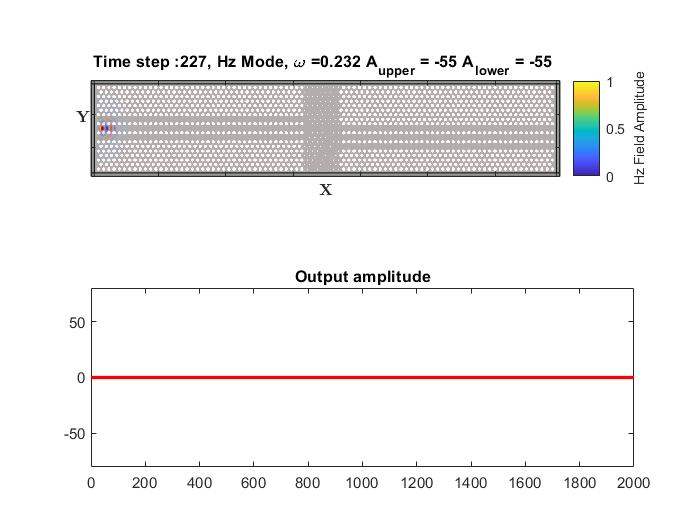

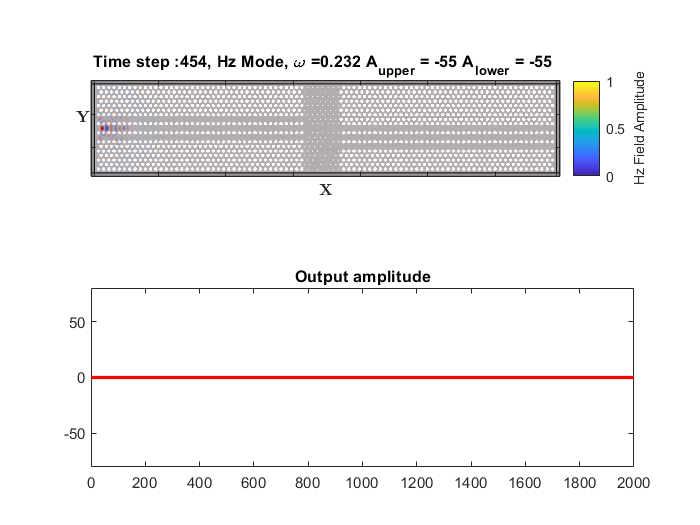

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        if ~mod(T,FPS)
            if DISPLAY_TRANSFER_WINDOW
                subplot(2,2,[1 2]);
            end
            OPTS.cmap = 'jet';
            if USE_HSRC
                OPTS.emax = src_max * 1.5;
            end
            if USE_TEZ_MODE
                if USE_ADVANCED_VISUALISATION
                    draw2d(ya,xa,ERx',Hz',NPML);
                else
                    imagesc(Hz);
                end
                if DISPLAY_LABELS
                    title(['Time step :', int2str(T),...
                        ', Hz Mode, \omega =', ...
                        num2str(NORMALIZED_FREQ), ' ',...
                        'A_{upper} = ',num2str(beam_upper_amp_AND), ' ',...
                        'A_{lower} = ',num2str(beam_lower_amp_AND), ' ']);
                end
            end
            axis image;
            if DISPLAY_LABELS
                gca;
                c = colorbar;
                c.Label.String = 'Hz Field Amplitude';
                caxis([-OPTS.emax OPTS.emax]);
                xlabel('$\mathbf{X}$','Interpreter', 'latex');
                ylabel('$\mathbf{Y}$        ','Interpreter', 'latex');
            end
            set(get(gca,'YLabel'),'Rotation',0)
            set(gca,'YTickLabel',[]);
            set(gca,'XTickLabel',[]);
            if DISPLAY_TRANSFER_WINDOW
                subplot(2,2,[3 4]);
%                 plot(,'b-','LineWidth', 2);
%                 hold on;
                plot(upper_guide_recording(863,:),'r-','LineWidth', 2);
                hold off;
                title('Output amplitude');
                ylim([-1 1] .* plotting_amp);
            end
            if RECORD_ANIMATION
                F = getframe(gcf);
                writeVideo(vidObj,F);
            end
            drawnow;
        end

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    end
%     return;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## AFTER LOOP STEPS

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
if RECORD_ANIMATION
    close(vidObj);
end

if DO_FULL_RECORDING
   save([sprintf('full_rec_%i_', ncase), file_name]);...,...
%        'middle_guide_recording', 'upper_guide_recording',...
%        'NCELL', 'bridge_cylinder_diamters','ERx'...
%         );
elseif RECORD_FIELDS
    %   clear Esrc_full Hsrc_full curr_trn_ex sigx sigy CHIx CHIy CHx CHy Dx Dy
    save(file_name, ...
        'curr_trn_hz_AND', 'curr_trn_hz_NOT', 'ERx', ...
        'dt','dx','dy',...
        'Hsrc_upper_beam_AND', 'Hsrc_lower_beam_AND', 'Hsrc_main_beam_AND', ...
        'Hsrc_upper_beam_NOT', 'Hsrc_lower_beam_NOT', 'Hsrc_main_beam_NOT', ...
        'Hsrc_full_AND','Hsrc_full_NOT','CHIx',...
        '-append');
end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## LAST STEPS

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
if PLAY_ON_FINISH
    load handel;
    player = audioplayer(y, Fs);
    play(player);
end
if SHUTDOWN_ON_EXIT
    system('shutdown');
end